# 8.1 Spectrum estimation

Alexandre Rey, MSE, MA-StatDig, 23.05.22

clear;
rng default;

addpath('../functions/');

## Periodogram resolution

The resolution of the periodogram, i.e. its ability to resolve closely spaced narrowband components is limited because of the Bartlett window. Since the width of the main lobe increases as $N$ decreases, for a given $N$ there is a limit on how closely two sinusoidal may be located before they can no longer be resolved. This is usually defined as the bandwidth of the window at its half power points (-6dB), which is for the Bartlett window at $0.89 \frac{2\pi}{N}$


$$\textrm{Res}\left\lbrace {\hat{P} }_{\textrm{per}} \left(e^{j\omega \;} \right)\right\rbrace =0\ldotp 89\frac{2\pi \;}{N}$$


This relation is valid for $\omega \in [-\pi...\pi]$. In the frequency domain, $f \in [-Fe/2...Fe/2]$, the bandwidth of the window at its half power points (-6dB) is :


$$\textrm{Res}\left\lbrace {\hat{P} }_{\textrm{per}} \left(e^{j\omega \;} \right)\right\rbrace =0\ldotp 89\frac{\textrm{Fe}}{N}$$


Let's take an example:  where $N$ is too low to separate 2 close sinusoids. In this example, the signal is a mixture of 2 sinusoids with $\omega = [0.4\pi, 0.45\pi]$ with random phase and with added Gaussian noise $v[n]$ ($\mu =0,\;\sigma =5$)


$$x\left\lbrack n\right\rbrack =A_1 \;\sin \left(n\omega_1 +\phi_1 \right)\;+A_2 \;\sin \left(n\omega_2 +\phi_2 \right)\;+v\left\lbrack n\right\rbrack$$


To evaluate the effect on the resolution, the number of point $N$ will be changed $N = [32; 128]$.

The process must be realized $N_r = 50$ times.

### Data Generation

#### Parameters

Set the parameters :

N = [32,128];               % process done on different N-size of signal
omega = [0.4*pi, 0.45*pi];  % angular frequency
sigmaV = 5;                 % standard deviation
A = [5, 5];                 % amplitude
Nr = 50;                    % times that processus is realized
NFFT = 512;

disp(table(N, omega, sigmaV, A, Nr, NFFT));

        N             omega          sigmaV      A       Nr    NFFT
    _________    ________________    ______    ______    __    ____

    32    128    1.2566    1.4137      5       5    5    50    512 



#### Generation

Generate the number of realization of the process and display it. For illustration, the processes are also generated once without noise. To generate the same process, follow the below instructions. Two processes are generated $x_1[n]$ and $x_2[n]$ which contains respectively 32 and 128 samples per realization.

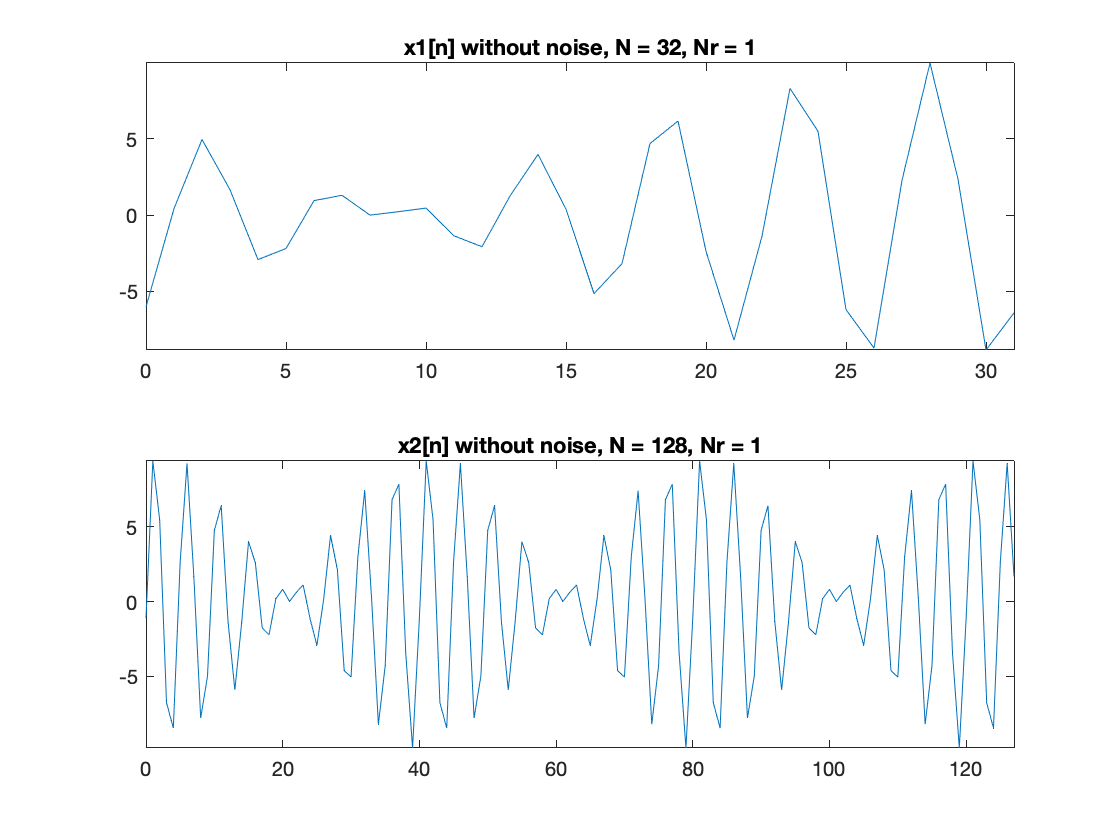

% random noise added to the signal
V1 =  sigmaV * randn(Nr, N(1));
V2 =  sigmaV * randn(Nr, N(2));

% random phase
Phi1 = rand(Nr, 2) * pi - pi;
Phi2 = rand(Nr, 2) * pi - pi;

% generate random process
n1 = 0:N(1)-1;
n2 = 0:N(2)-1;
x1 = A(1)*sin(n1*omega(1)+Phi1(:,1)) + A(2)*sin(n1*omega(2)+Phi1(:,2)) + V1;
x2 = A(1)*sin(n2*omega(1)+Phi2(:,1)) + A(2)*sin(n2*omega(2)+Phi2(:,2)) + V2;

nr=1;
figure;
subplot(2,1,1);
    plot(n1, x1(nr,:)-V1(nr,:))
    title(['x1[n] without noise, N = ', num2str(N(1)), ', Nr = ', num2str(nr)])
    axis tight
subplot(2,1,2);
    plot(n2, x2(nr,:)-V2(nr,:))
    title(['x2[n] without noise, N = ', num2str(N(2)), ', Nr = ', num2str(nr)])
    axis tight

figure;
subplot(2,1,1);
    plot(n1, x1);
    title(['x_1[n] with noise, N = ', num2str(N(1)), ', Nr = 1..', num2str(Nr)]);
    xlabel('n');
    axis tight
subplot(2,1,2);
    plot(n2, x2);
    title(['x_2[n] with noise, N = ', num2str(N(2)), ', Nr = 1..', num2str(Nr)]);
    ylabel('n');
    axis tight

#### Periodogram

The following is computing the periodogram for both processes and all realizations. Then, the average periodograms are computed.

Knowing the number of points, the red line are showing the theoretical resolution centered on the first frequency.

The dotted line is showing the theoretical amplitude of the spectrum.

- To build the figure, you must start to design the function `myPer()` described at the end of the mlx.

- Then, create a loop on the realization and compute the periodogram for each realization of each signal $x_1$ and $x_2$

- Then, compute the average of all the realizations.

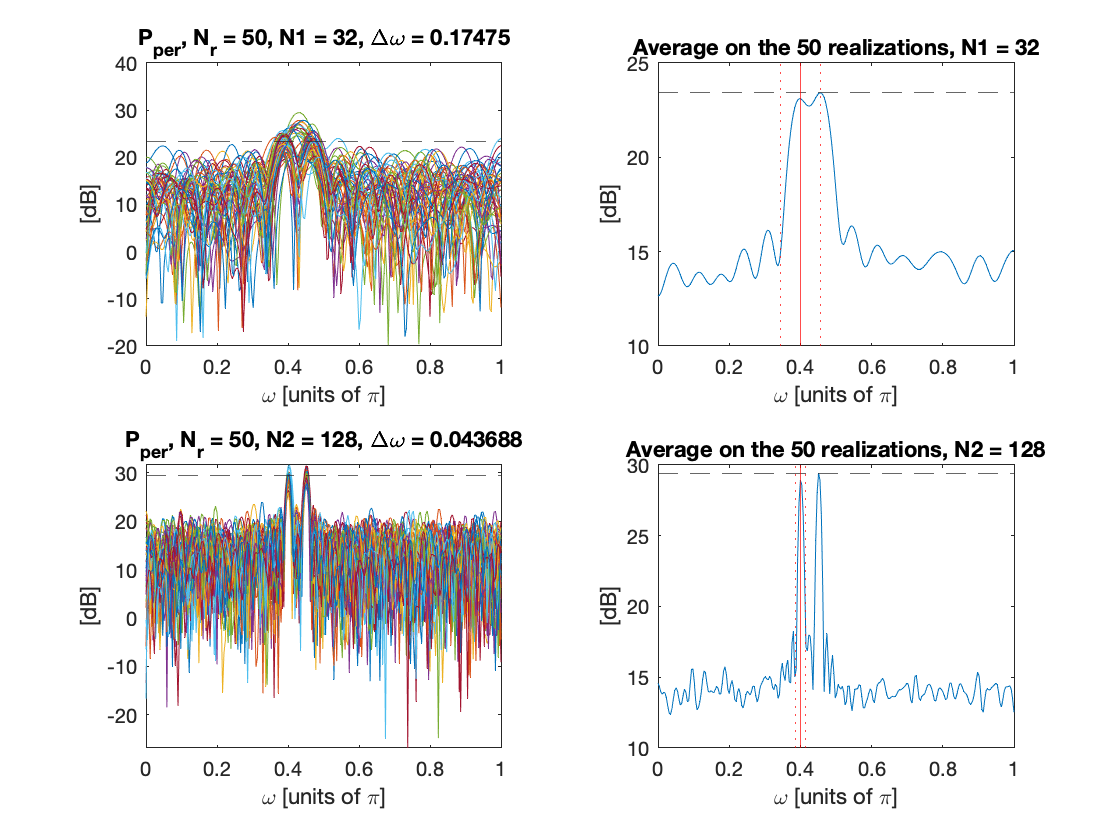

w_vec = linspace(0, 1, NFFT/2);
Px1 = zeros(Nr, NFFT/2);            % Nr realizations of NFFT/2 points
Px2 = zeros(Nr, NFFT/2);
for i=1:Nr
    Px1(i, :) = myPer(x1(i,:), NFFT);
    Px2(i, :) = myPer(x2(i,:), NFFT);
end

Px1_dB = 10*log10(Px1);
Px2_dB = 10*log10(Px2);

Px1_mean_dB = 10*log10(mean(Px1, 1));
Px2_mean_dB = 10*log10(mean(Px2, 1));

delta_omega = 0.89*2*pi./N; % bandwidth of the window

tiledlayout(2,2)
t1=nexttile;
    plot(w_vec, Px1_dB)
    yline(max(Px1_mean_dB), '--')
    title(['P_{per}, N_r = ', num2str(Nr), ', N1 = ', num2str(N(1)), ', \Delta\omega = ', num2str(delta_omega(1))])
    xlabel('\omega [units of \pi]')
    ylabel('[dB]')
    ylim([-20 40])
t2=nexttile;
    plot(w_vec, Px1_mean_dB)
    yline(max(Px1_mean_dB), '--')
    xline((omega(1)+delta_omega(1))/pi, 'r:')
    xline(omega(1)/pi, 'r-')
    xline((omega(1)-delta_omega(1))/pi, 'r:')
    title(['Average on the ', num2str(Nr), ' realizations, N1 = ', num2str(N(1))])
    xlabel('\omega [units of \pi]')
    ylabel('[dB]')
    ylim([10 25])
t3=nexttile;
    plot(w_vec, Px2_dB)
    yline(max(Px2_mean_dB), '--')
    title(['P_{per}, N_r = ', num2str(Nr), ', N2 = ', num2str(N(2)), ', \Delta\omega = ', num2str(delta_omega(2))])
    xlabel('\omega [units of \pi]')
    ylabel('[dB]')
    axis tight
t4=nexttile;
    plot(w_vec, Px2_mean_dB)
    yline(max(Px2_mean_dB), '--')
    xline((omega(1)+delta_omega(2))/pi, 'r:')
    xline(omega(1)/pi, 'r-')
    xline((omega(1)-delta_omega(2))/pi, 'r:')
    title(['Average on the ', num2str(Nr), ' realizations, N2 = ', num2str(N(2))])
    xlabel('\omega [units of \pi]')
    ylabel('[dB]')
    ylim([10 30])
linkaxes([t1,t2,t3,t4], 'x');

## Modified Periodogram

Instead of applying a rectangular window to $x[n]$ to make it finite length, other kind of windows could be used.

This degree of freedom can be used to modulate the amount of smoothing to be applied to the periodogram. Although a rectangular window has a narrow main lobe compared to other windows and therefore, produces the least amount of spectral smoothing, it has relatively large sidelobes that may lead to the masking of weak narrowband components.

### Process Generation

Lets start to generate the same process than before but with different values:

 $\omega = [0.25\pi, 0.3\pi]$ with random phase and with added Gaussian noise v[n] ($\mu =0,\;\sigma =0\ldotp 3$)


$$x\left\lbrack n\right\rbrack =A_1 \;\sin \left(n\omega_1 +\phi_1 \right)\;+A_2 \;\sin \left(n\omega_2 +\phi_2 \right)\;+v\left\lbrack n\right\rbrack$$


Where the amplitude is $A_1 =0\ldotp 1$ and $A_2 =1$. Only $N=256$ samples are generated for each of the 20 realizations.

N3 = 256;
N = [N, N3];
omega = [0.25*pi, 0.3*pi];
A = [0.1, 1];
Nr = 20;
sigmaV = 0.3;
NFFT = 2048;
disp(table(N3, omega, A, Nr, sigmaV, NFFT));

    N3           omega              A         Nr    sigmaV    NFFT
    ___    _________________    __________    __    ______    ____

    256    0.7854    0.94248    0.1      1    20     0.3      2048



Below is the generated process x3[n]:

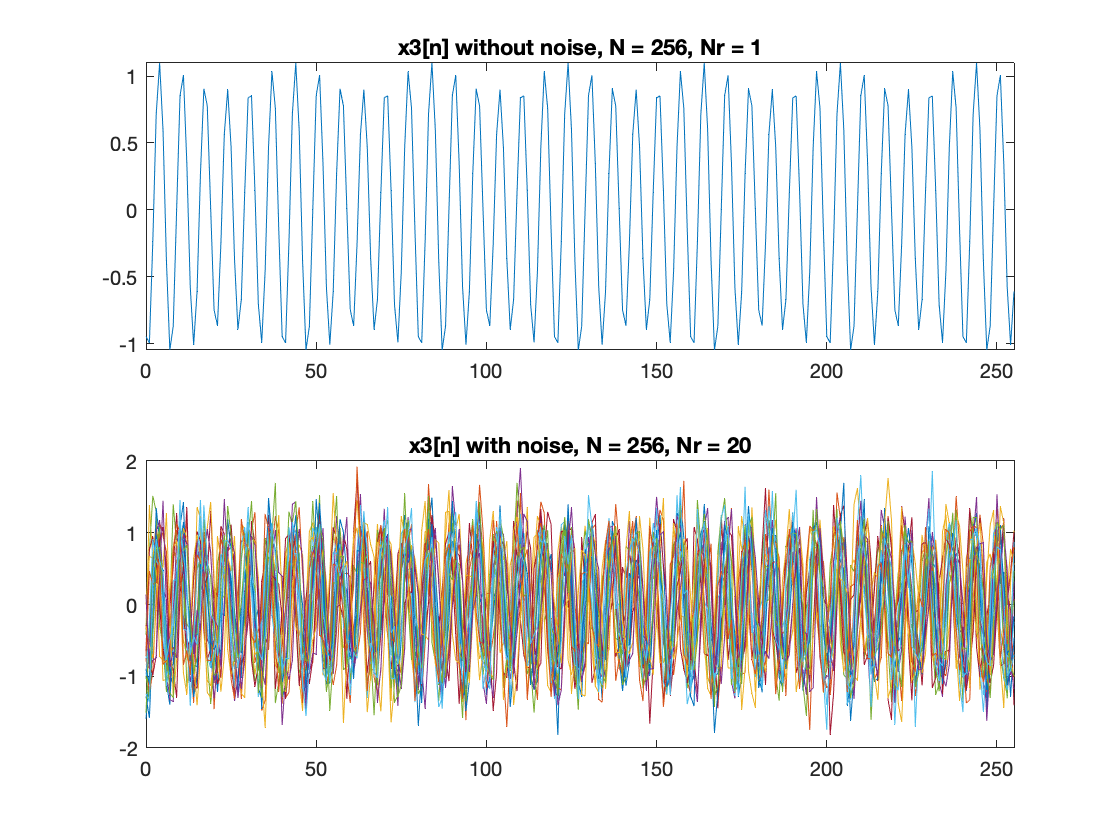

V3 =  sigmaV * randn(Nr, N(3));

% random phase
Phi3 = rand(Nr, 2) * pi - pi;

% Generate random process
n3 = 0:N(3)-1;

x3 = A(1)*sin(n3*omega(1)+Phi3(:,1)) + A(2)*sin(n3*omega(2)+Phi3(:,2)) + V3;

figure;
subplot(2,1,1);
    plot(n3, x3(1,:)-V3(1,:))
    title(['x3[n] without noise, N = ', num2str(N(3)), ', Nr = 1'])
    axis tight
subplot(2,1,2);
    plot(n3, x3(1:20,:))
    title(['x3[n] with noise, N = ', num2str(N(3)), ', Nr = 20'])
    axis tight
    ylim([-2 2])

### Windows analysis

The modified periodogram can use different windows. For this example, we will use only hamming window instead of the rectangular window. As the spectrum will be a convolution with the square fourier transform of the window, it is interesting to look the window spectrum. To achive that:

- Create the rectangular and hamming windows using N points

- Normalize the windows by their respective norm (norm())

- Compute the DTFT using NFFT points

The rectangular window is easily computed using ones(1,N). The hamming window is easily generated with wh=*hamming(N)*. Below, the two windows are compared:

% Rectangular window
Rw = ones(N3,1);
Rw = Rw/norm(Rw);

% Hamming window
Hw = hamming(N3);
Hw = Hw/norm(Hw);

Rw_dB = 10*log10(Rw);
Hw_dB = 10*log10(Hw);

Rw_fft = 20*log10(fftshift(abs(fft(Rw, NFFT)/N3)));
Hw_fft = 20*log10(fftshift(abs(fft(Hw, NFFT)/N3)));
w_vec  = linspace(-pi, pi, length(Rw_fft));

figure
subplot(1,2,1)
    plot(n3, Rw, ...
         n3, Hw)
    title('Normalized windows : w_r/||w_r||')
    legend('rectangular', 'hamming')
    xlabel('n')
    axis tight
    ylim([0 0.15])
subplot(1,2,2)
    plot(w_vec, Rw_fft, ...
         w_vec, Hw_fft)
    title('W(\omega)')
    xlabel('\omega')
    ylabel('[dB]')
    axis tight
    ylim([-150 0]);

### Estimated power spectrum density

The periodogram and modified periodogram (hamming) are used to estimate the power spectrum density of the realizations. The periodogram is computed for each realization and one realization (first) is also displayed. 

- To build the figure, you must start to design the function myMper() described at the end of the mlx.

w_vec = linspace(0, 1, NFFT/2);
Px3 = zeros(Nr, NFFT/2);            % Nr realizations of NFFT/2 points
Px3_hamming = zeros(Nr, NFFT/2);    % Nr realizations of NFFT/2 points
for i=1:Nr
    Px3_hamming(i, :) = myMper(x3(i,:), NFFT, 'hamming');
    Px3(i, :) = myPer(x3(i,:), NFFT);
end

Px3_hamming_dB = 10*log10(Px3_hamming);
Px3_dB = 10*log10(Px3);

delta_omega3 = 0.89*2*pi./N3; % bandwidth of the window

tiledlayout(2,2)
t1=nexttile;
    plot(w_vec, Px3_dB)
    title(['P_{periodigram}, N_r=1:', num2str(Nr), ', N=', num2str(N3)])
    xlabel('\omega')
    ylabel('[dB]')
t2=nexttile;
    plot(w_vec, Px3_dB(1,:))
    xline(omega(1)/pi, 'r-')
    xline(omega(2)/pi, 'g-')
    title(['P_{periodigram}, N_r=1', ', N=', num2str(N3)])
    xlabel('\omega')
    ylabel('[dB]')
t3=nexttile;
    plot(w_vec, Px3_hamming_dB)
    title(['P_{modified (hamming)}, N_r=1:', num2str(Nr), ', N=', num2str(N3)])
    xlabel('\omega')
    ylabel('[dB]')
t4=nexttile;
    plot(w_vec, Px3_hamming_dB(1,:))
    xline(omega(1)/pi, 'r-')
    xline(omega(2)/pi, 'g-')
    title(['P_{modified (hamming)}, N_r=1', ', N=', num2str(N3)])
    xlabel('\omega')
    ylabel('[dB]')
linkaxes([t1,t2,t3,t4], 'x');

Finally, the average periodograms are displayed below:

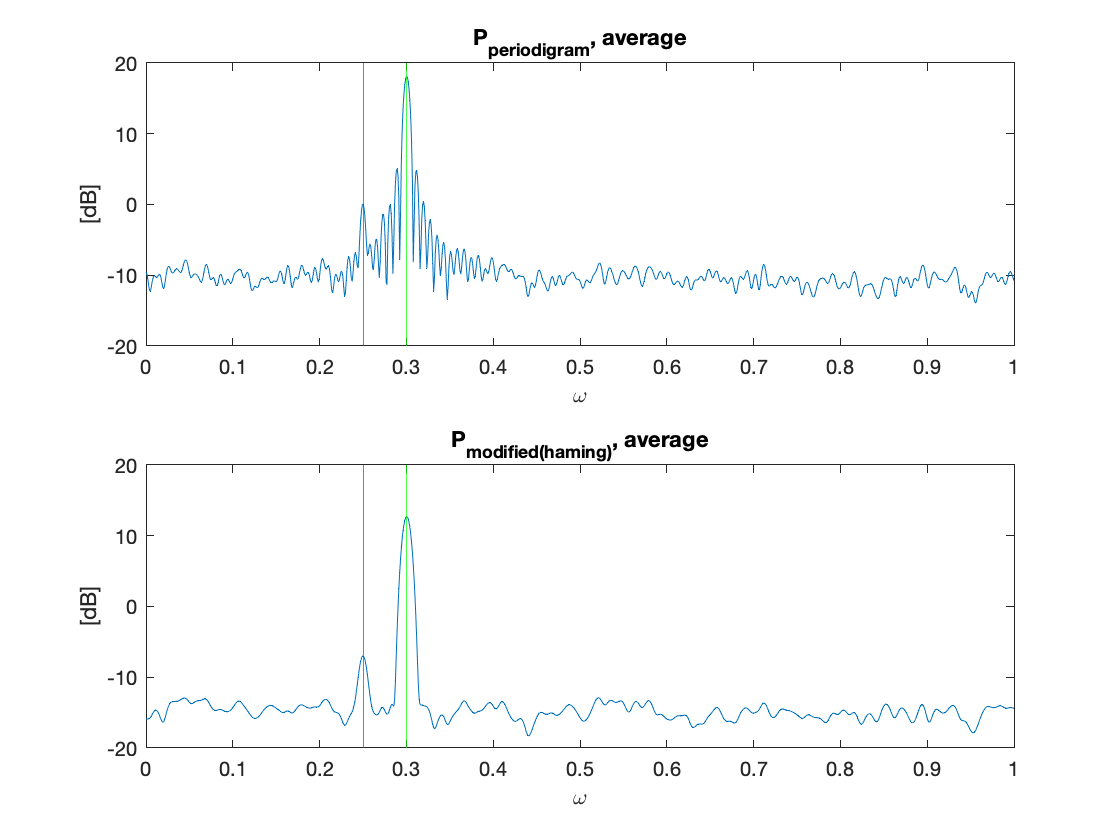

Px3_mean_dB = 10*log10(mean(Px3, 1));
Px3_mean_hamming_dB = 10*log10(mean(Px3_hamming, 1));

tiledlayout(2,1);
t1=nexttile;
    plot(w_vec, Px3_mean_dB);
    xline(omega(1)/pi, 'r-');
    xline(omega(2)/pi, 'g-');
    title('P_{periodigram}, average');
    xlabel('\omega');
    ylabel('[dB]');
t2=nexttile;
    plot(w_vec, Px3_mean_hamming_dB);
    xline(omega(1)/pi, 'r-');
    xline(omega(2)/pi, 'g-');
    title('P_{modified(haming)}, average');
    xlabel('\omega')
    ylabel('[dB]')
linkaxes([t1,t2], 'xy');